# Simulación de Montecarlo 

clear;
clc;

## a) Procedemos a crear las muestras de las variables que usaremos para el desarrollo de la simulación de Montecarlo.

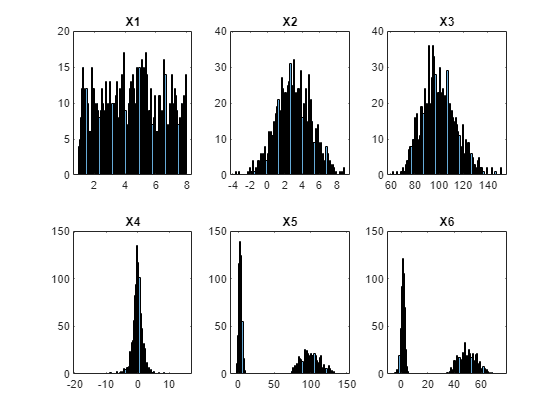

% Primero creamos X1 hasta X6 e Y
s = 1000;
X1 = 1 + (8-1)*rand(s,1);
X2 = randn(s,1)*2 + 3;

X3 = randn(s,1).^2;
for i = 1:99
    X3 = X3 + randn(s,1).^2;
end

X4 = randn(s,1)./( (randn(s,1).^2 + randn(s,1).^2) /2).^0.5;

u = rand(s,1); 
X5 = (u>0.5).*X2 + (1-(u>0.5)).*X3;

X6 = (X4 + X5)*(0.5) + 0.1 * randn(s,1);

Y = -(1/0.6)*log(1-rand(s,1));

X = [X1 X2 X3 X4 X5 X6];

% graficamos

subplot(2,3,1)
histogram(X1,100);
title('X1');

subplot(2,3,2)
histogram(X2,100);
title('X2');

subplot(2,3,3)
histogram(X3,100);
title('X3');

subplot(2,3,4)
histogram(X4,100);
title('X4');

subplot(2,3,5)
histogram(X5,100);
title('X5');

subplot(2,3,6)
histogram(X6,100);
title('X6');

## b y c) Como me percaté de que pedían el mismo algoritmo de muestreo aleatorio, cree una función llamada Data_sample(), basicamente hace lo que me están pidiendo. Dicha función es mi versión de "random", la cual le pusé otro nombre puesto que tendía a confundirme con otras funciones que existen en matlab. 

## Es muy relevante notar que la función Data_sample() entrega una matriz como cualquier otra, sin embargo, está es tridimensional. Cada fila corresponde a un elemento de la muestra en particular, cada columna es una variable diferente, y la tercera dimensión de la matriz es cada muestra en su totalidad. En el caso de X, las filas son los 100 elementos de cada variable en particular, las columnas son las 6 variables distintas en X, y la tercera dimensión corresponde a las 1000 muestras diferentes. En resumen, una matriz de 100x6x1000.

% sacamos las muestras de X
SX = Data_sample(1000, 100, X);

% muestras de Y
SY = Data_sample(1000, 100, Y);

## d) Procedemos con estudio estadístico de cada elemento de SX, lo que es muy simple puesto que matlab se basa en las operaciones matrciales. 

## La estimación por mínimos cuadrados ordinarios se hace de forma matricial con una función especial que calculará un beta distinto por cada muestra extraida en el inciso anterior. Es decir, está función entregará una matriz tridimencional, donde cada fila es un "beta" distinto, incluyendo el coeficiente de posición. En otras palabras, la matriz "betas" es de 7x1x1000. 

media = mean(SX,1);
mediana = prctile(SX, 50, 1);
mini = min(SX);
maxi = max(SX);
vari = var(SX);
pc_25 = prctile(SX, 25, 1);
pc_75 = prctile(SX, 75, 1);

% creamos los valores 1 para el coeficiente de posicion y estimamos OLS
aux = ones(100, 1, 1000);

% juntamos los unos con los datos
SX_est = [aux  SX];

% usamos la funcion betas
betas = Betas(SX_est, SY);

## e) Computamos betas de una muestra cualquiera

betas(:, :, 1)

ans =     4.0730
   -0.0422
   -0.1132
   -0.0191
   -0.1243
    0.0043
    0.0022


## f) La matriz ya existe, se llama "betas".

## g) Usaremos una funcion e iteramos con el tamano de las muestras

Data = [];
i = 0;
for s = [10^2 10^3 10^4 10^5]
    i = i + 1;
    Data(i, :, :) = All_betas(1000, s, X, Y); 
end

## Graficamos

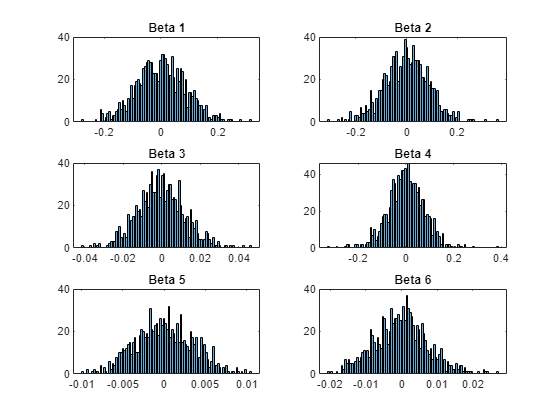

%% graficamos

n = 0;
figure('Name', '100 muestras de Tamaño 100');
for j = 1: (size(Data, 2) - 1)
n = n + 1;
subplot(3, 2, n);
histogram(Data(1, j + 1, :), 100);
title(strcat("Beta ", num2str(j)));
end

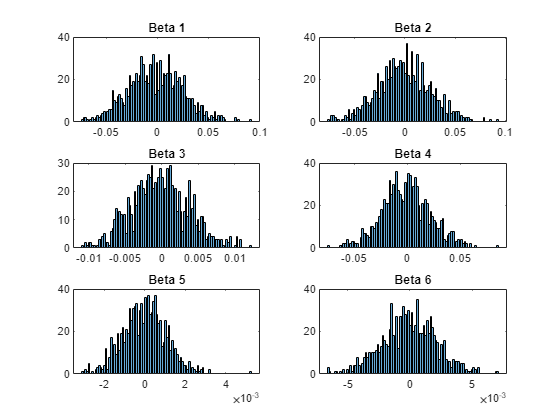


n = 0;
figure('Name', '100 muestras de Tamaño 1000');
for j = 1: (size(Data, 2) - 1)
n = n + 1;
subplot(3, 2, n);
histogram(Data(2, j + 1, :), 100);
title(strcat("Beta ", num2str(j)));
end

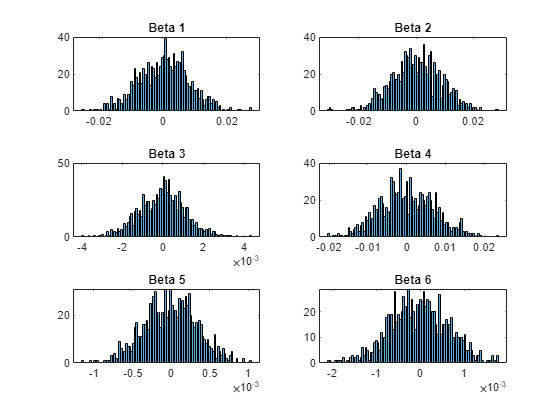


n = 0;
figure('Name', '100 muestras de Tamaño 10000');
for j = 1: (size(Data, 2) - 1)
n = n + 1;
subplot(3, 2, n);
histogram(Data(3, j + 1, :), 100);
title(strcat("Beta ", num2str(j)));
end


n = 0;
figure('Name', '100 muestras de Tamaño 100000');
for j = 1: (size(Data, 2) - 1)
n = n + 1;
subplot(3, 2, n);
histogram(Data(4, j + 1, :), 100);
title(strcat("Beta ", num2str(j)));
end

Unrecognized function or variable 'Data'.

## El tamaño de las muestras no hace una gran diferencia en las distribuciones de los "beta" estimados, pero veamos que ocurre en caso de que aumentemos el número de muestras.

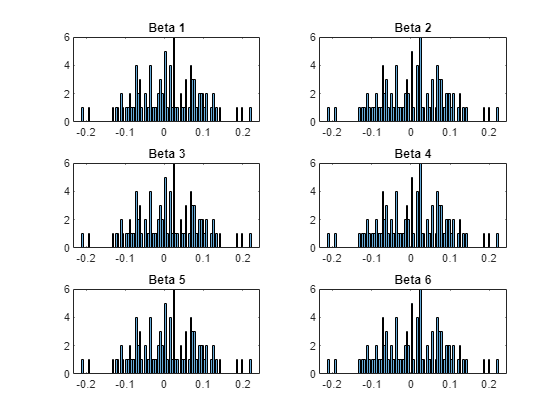

Data_n = All_betas(100, 100, X, Y);

n = 0;
figure('Name', '100 muestras de tamaño 100');
for i = 2:size(Data_n, 1)
n = n + 1;
subplot(3, 2, n);    
histogram(Data_n(2, :, :), 100);
title(strcat("Beta ", num2str(i - 1)));
end

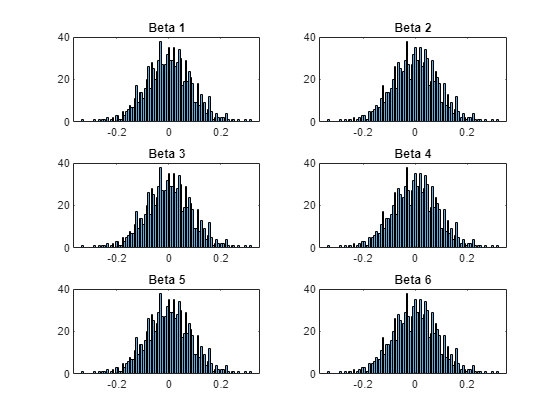

Data_n = All_betas(1000, 100, X, Y);

n = 0;
figure('Name', '1000 muestras de tamaño 100');
for i = 2:size(Data_n, 1)
n = n + 1;
subplot(3, 2, n);    
histogram(Data_n(2, :, :), 100);
title(strcat("Beta ", num2str(i - 1)));
end

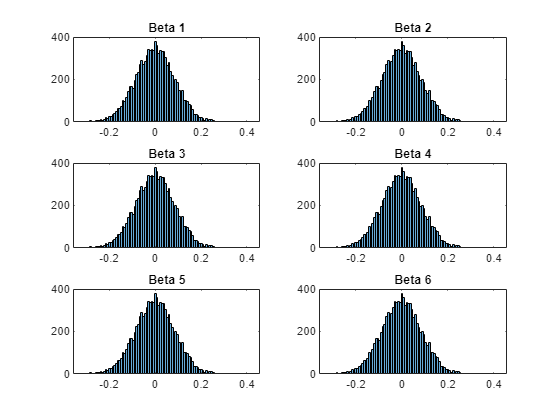

Data_n = All_betas(10000, 100, X, Y);

n = 0;
figure('Name', '10000 muestras de tamaño 100');
for i = 2:size(Data_n, 1)
n = n + 1;
subplot(3, 2, n);    
histogram(Data_n(2, :, :), 100);
title(strcat("Beta ", num2str(i - 1)));
end

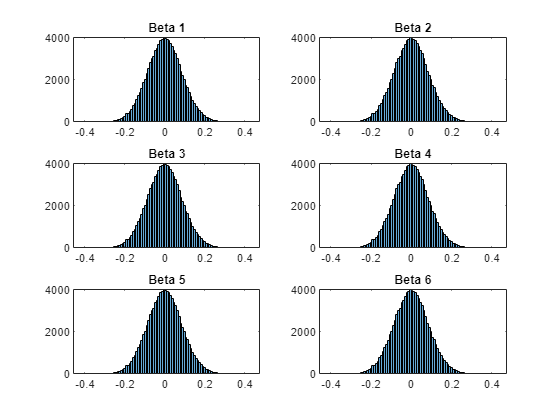

Data_n = All_betas(100000, 100, X, Y);

n = 0;
figure('Name', '100000 muestras de tamaño 100');
for i = 2:size(Data_n, 1)
n = n + 1;
subplot(3, 2, n);    
histogram(Data_n(2, :, :), 100);
title(strcat("Beta ", num2str(i - 1)));
end

## h) iteramos nuevamente con la cantidad de muestras

Data_n = All_betas(100000, 100, X, Y);

## graficamos

histogram(Data_n(1, 1, :));

## usefull functions

% usare matrices de tres dimensiones


function Data = All_betas(n, s, X, Y)
SX = Data_sample(n, s, X);
SY = Data_sample(n, s, Y);
aux = ones(s, 1, n);
SX_est = [aux  SX];

Data = Betas(SX_est, SY); 
end

function B = Betas(X, Y)
B = [];
for i = 1:size(X, 3)
    x = X(:, :, i);
    y = Y(:, :, i);
    B(:, :, i) = (x' * x)\x' * y;
end
end

function Samples = Data_sample(n, s, X)
Samples = [];
for i = 1:n
    % genera cada muestra
    SX = [];
    for i_1 = 1:size(X,2)
        SX(:,i_1) = Sample(s, X(:,i_1)');
    end
% se guarda cada muestra en un objetop tridimensional 
Samples(:,:,i) = SX;
end
end

% saca mvectores que corresponden a muestras de n elementos
function Samp = Sample(n, vector)
Samp = [];
for i = 1:n
Samp(i) = vector(randi(length(vector)));
end
Samp = Samp';
end